init();
M = 38; % number of harmonics
T = 2; % waveform period 2s
[m,cm] = create_cm_series(M,T); % create fourier coefficients

t = 0:4/1000:4; % 1001 points from 0 sec to 4 sec
[y] = cm2yt(t,T,m,cm,M);
make_plot(t,y,'sawtooth to verify M = 38','t sec','y');

make_stem(m,cm,'Spectrum','harmonic','Fourier coefficient');
% Find power
Pcm = (abs(cm).*abs(cm));
make_stem(m,Pcm,'Power Spectrum','harmonic','power');
%Find cumulative power in spectrum lines
% Find zero element in m
zero_ind=find(m == 0);
% Find all positive values in m (1 through M)
pos_ind=find(m > 0 & m <= M);
Pcm_harmonic = [Pcm(zero_ind) 2*Pcm(pos_ind)];
make_stem([0:M],cumsum(Pcm_harmonic),'Cumulative Power Spectrum','harmonic','cumulative power');




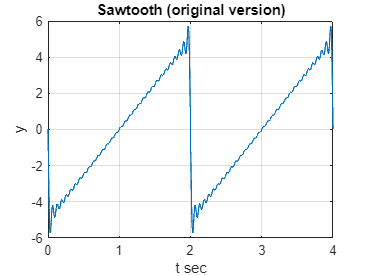


init();
M = 31;
T = 2; % waveform period 2s
[m,cm] = create_cm_series(M,T); % create Fourier coefficients
t = 0:4/1000:4; % 1001 points from 0 sec to 4 sec
% original sawtooth
[y] = cm2yt(t,T,m,cm,M);
make_plot(t,y,'Sawtooth (original version)','t sec','y');

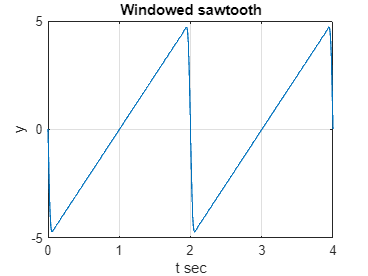

% windowed sawtooth
win = hamming(2*M+1)'; %Hamming window
cwin = cm.*win; %Windowed Fourier coefficients
[ywin] = cm2yt(t,T,m,cwin,M); % <---- Complete this line
make_plot(t,ywin,'Windowed sawtooth','t sec','y');